DATA= readtable("Training data.xlsx","TextType","string")

DATA = 9417×2 table
             Measure_Name                                                              Description                                                 
    ______________________________    _____________________________________________________________________________________________________________

    "Bulb - Exterior"                 ""(1) 12w ledt8 lamp + 1l ballast lighting""                                                                 
    "Bulb - Exterior"                 ""(1) 16.5w led instantfit tubes & 1-lamp none advance ballast lighting""                                    
    "Bulb - Exterior"                 ""(1) 16.5w ledt8 lamp + 1h ballast lighting""                                                               
    "Lighting Controls - Exterior"    ""(1) 2-pole circuit dimmer lighting""                                                                       
    "VFD - Cooling"    


DATA.Measure_Name = categorical(DATA.Measure_Name)

DATA = 9417×2 table
            Measure_Name                                                             Description                                                 
    ____________________________    _____________________________________________________________________________________________________________

    Bulb - Exterior                 ""(1) 12w ledt8 lamp + 1l ballast lighting""                                                                 
    Bulb - Exterior                 ""(1) 16.5w led instantfit tubes & 1-lamp none advance ballast lighting""                                    
    Bulb - Exterior                 ""(1) 16.5w ledt8 lamp + 1h ballast lighting""                                                               
    Lighting Controls - Exterior    ""(1) 2-pole circuit dimmer lighting""                                                                       
    VFD - Cooling                  

summary(DATA.Measure_Name)

     Air Compressor                        63 
     Air Nozzle                             2 
     Air Sealing                          136 
     Air Source                            21 
     Appliance Removal                    113 
     Boiler                               128 
     Boiler Reset Control                  21 
     Building Operator Certification        2 
     Bulb - Exterior                      537 
     Bulb - Interior                        4 
     CHP                                   26 
     Central AC                            20 
     Chiller                               59 
     Circulator Pump                       16 
     Clothes Dryer                          8 
     Clothes Washer    

# **Vending Miser**

Labeldata=DATA(ismember(DATA.Measure_Name,"Vending Miser"),:)

Labeldata = 86×2 table
    Measure_Name                                                    Description                                                
    _____________    __________________________________________________________________________________________________________

    Vending Miser    ""1 vend/coolermiser other""                                                                              
    Vending Miser    ""4322429 | refrigeration | vending misers | vending misers refrigeration""                               
    Vending Miser    ""4338673 | refrigeration | vending misers | vending misers refrigeration""                               
    Vending Miser    ""4344427 | refrigeration | vending misers | vending misers refrigeration""                               
    Vending Miser    ""4363040 | refrigeration | 425851 | vending misers | vending misers | 894 refrigeration""                
    Vending 

Labeldata_D=string(Labeldata.Description)

Labeldata_D = 86×1 string array
    ""1 vend/coolermiser other""
    ""4322429 | refrigeration | vending misers | vending misers refrigeration""
    ""4338673 | refrigeration | vending misers | vending misers refrigeration""
    ""4344427 | refrigeration | vending misers | vending misers refrigeration""
    ""4363040 | refrigeration | 425851 | vending misers | vending misers | 894 refrigeration""
    ""4363945 | refrigeration | vending misers | vending misers refrigeration""
    ""4514545 | refrigeration | vending misers | vending misers refrigeration""
    ""4550003 | refrigeration | vending misers | vending misers refrigeration""
    ""4553356 | refrigeration | vending misers | glass front cooler misers refrigeration""
    ""4557274 | refrigeration | vending misers | cooler misers refrigeration""
    ""4625118 | refrigeration | vending misers | vending misers refrigeration""
    ""4687972 | refrigeration | vending misers | vending misers refrigeration""
    ""4762009 | refrigeration 

   % Convert to numeric
    Labeledior2Num = pdist(Labeldata_D)

Labeledior2Num =   527.4268  526.0048  526.9488  546.5666  526.0561  527.0873  527.8901  576.4304  521.5113  527.6779  525.2771  654.4074  526.1435  517.6785  518.3223  518.6203  520.4364  653.4195  653.2886  390.4510  368.0625  287.6491  301.8592  319.7687  319.6514  505.2564  340.2602  508.6453  771.2354  605.9150  606.2937  606.1163  624.4958  701.2852  618.2176  506.7248  337.6996  489.7816  403.7536  416.5693  481.1746  489.2699  483.9432  384.7350  728.4909  484.8866  623.9223  608.3198  672.2596  744.1364


    labeledLink = linkage(Labeledior2Num,"ward")

labeledLink = 	1.0e+03 *

    0.0190    0.0200    0.0026
    0.0020    0.0040    0.0035
    0.0540    0.0560    0.0048
    0.0070    0.0880    0.0055
    0.0310    0.0330    0.0057
    0.0110    0.0900    0.0059
    0.0030    0.0120    0.0067
    0.0060    0.0930    0.0073
    0.0150    0.0170    0.0080
    0.0530    0.0890    0.0089


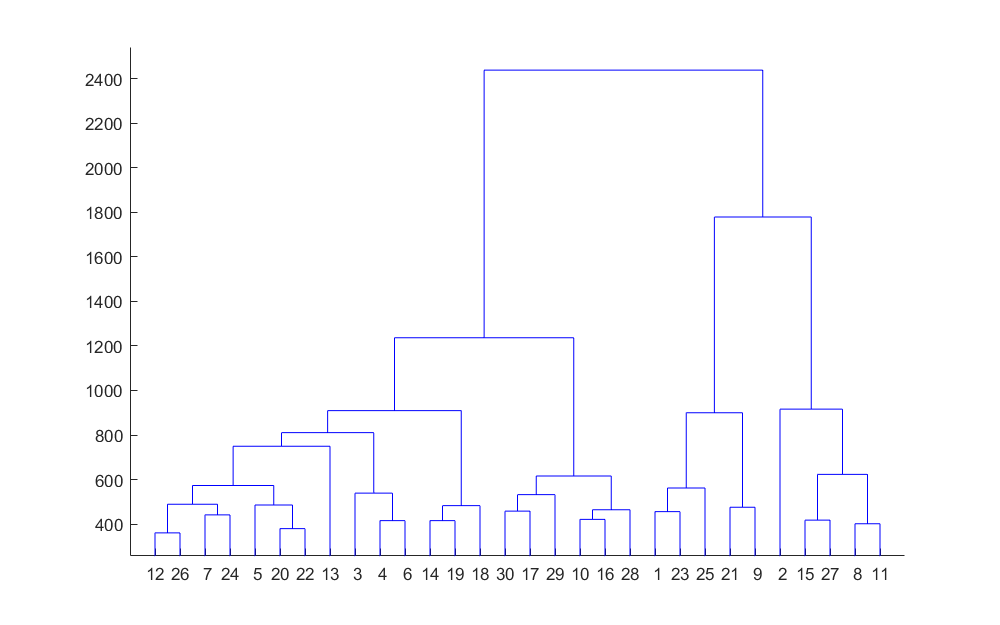

   
    % View tree
    dendrogram(labeledLink)


    % Accuracy Measure
    Labeled_ACC = cophenet(labeledLink,Labeledior2Num)

Labeled_ACC = 0.7653

    % Use inconsistency Coeff to help decide optimal # of cluster
    Labeled_I = inconsistent(labeledLink)

Labeled_I = 	1.0e+03 *

    0.0026         0    0.0010         0
    0.0035         0    0.0010         0
    0.0048         0    0.0010         0
    0.0045    0.0015    0.0020    0.0007
    0.0057         0    0.0010         0
    0.0057    0.0003    0.0020    0.0007
    0.0067         0    0.0010         0
    0.0070    0.0004    0.0020    0.0007
    0.0080         0    0.0010         0
    0.0068    0.0029    0.0020    0.0007


   
   Numberofcluster=2

Numberofcluster = 2

   
     % Agglomerative Heirarichical Cluster
     Labeled_Cluster = cluster(labeledLink,"maxclust",Numberofcluster)

Labeled_Cluster =      2
     2
     2
     2
     1
     2
     2
     2
     1
     2


   
     % Assign Cluster to Measure name
     Labeled_Idx = table(Labeldata_D,Labeled_Cluster)

Labeled_Idx = 86×2 table
                                                   Labeldata_D                                                    Labeled_Cluster
    __________________________________________________________________________________________________________    _______________

    ""1 vend/coolermiser other""                                                                                         2       
    ""4322429 | refrigeration | vending misers | vending misers refrigeration""                                          2       
    ""4338673 | refrigeration | vending misers | vending misers refrigeration""                                          2       
    ""4344427 | refrigeration | vending misers | vending misers refrigeration""                                          2       
    ""4363040 | refrigeration | 425851 | vending misers | vending misers | 894 refrigeration""                           1    


Cluster_1 = Labeled_Idx(Labeled_Cluster == 1,"Labeldata_D")

Cluster_1 = 32×1 table
                          Labeldata_D                       
    ________________________________________________________

    ""1 vend/coolermiser other""                            
    ""add vending miser - occ sensor refrigeration""        
    ""add vending miser - sensor vm150 refrigeration""      
    ""adding vending miser refrigeration""                  
    ""alpha q - vending miser cooling""                     
    ""control w/ vending miser refrigeration""              
    ""control w/ vending timer refrigeration""              
    ""digtial timer for vending refrigeration""             
    ""new vending unit controls refrigeration""             
    ""refigerated beverage vending machine refrigeration""  
    ""refrigerated beverage vending machines refrigeration""
    ""refrigerated snack vending machines refrigeration""   
    ""sm170 vending miser refrigeration""                   
    ""vend miser lighting""

Cluster_2 = Labeled_Idx(Labeled_Cluster == 2,"Labeldata_D")

Cluster_2 = 23×1 table
                                    Labeldata_D                                 
    ____________________________________________________________________________

    ""4322429 | refrigeration | vending misers | vending misers refrigeration"" 
    ""4338673 | refrigeration | vending misers | vending misers refrigeration"" 
    ""4344427 | refrigeration | vending misers | vending misers refrigeration"" 
    ""4363945 | refrigeration | vending misers | vending misers refrigeration"" 
    ""4514545 | refrigeration | vending misers | vending misers refrigeration"" 
    ""4550003 | refrigeration | vending misers | vending misers refrigeration"" 
    ""4557274 | refrigeration | vending misers | cooler misers refrigeration""  
    ""4625118 | refrigeration | vending misers | vending misers refrigeration"" 
    ""4687972 | refrigeration | vending misers | vending misers refrigeration"" 
    ""4787093 | refrigeration | vending misers | ve

Cluster_3 = 31×1 table
                                                                        Labeldata_D                                                                     
    ____________________________________________________________________________________________________________________________________________________

    ""4363040 | refrigeration | 425851 | vending misers | vending misers | 894 refrigeration""                                                          
    ""4553356 | refrigeration | vending misers | glass front cooler misers refrigeration""                                                              
    ""4762009 | refrigeration | vending misers | refrigerated beverage vending machine control refrigeration""                                          
    ""5092323 | refrigeration | vending misers | refrigerated beverage vending machine control refrigeration""                                          
    ""5094234 | refriger


Cluster_1_CL=preprocessText(Cluster_1.Labeldata_D)

Cluster_1_CL =   32×1 tokenizedDocument:

    2 tokens: vend coolermiser
    6 tokens: add vending miser occ sensor refrigeration
    6 tokens: add vending miser sensor vm150 refrigeration
    4 tokens: adding vending miser refrigeration
    4 tokens: alpha vending miser cooling
    4 tokens: control vending miser refrigeration
    4 tokens: control vending timer refrigeration
    4 tokens: digtial timer vending refrigeration
    5 tokens: new vending unit controls refrigeration
    5 tokens: refigerated beverage vending machine refrigeration
    5 tokens: refrigerated beverage vending machines refrigeration
    5 tokens: refrigerated snack vending machines refrigeration
    4 tokens: sm170 vending miser refrigeration
    3 tokens: vend miser lighting
    3 tokens: vending control refrigeration
    3 tokens: vending controls refrigeration
    5 tokens: vending machine central controls refrigeration
    5 tokens: 

Cluster_2_CL=preprocessText(Cluster_2.Labeldata_D)

Cluster_2_CL =   23×1 tokenizedDocument:

     7 tokens: 4322429 refrigeration vending misers vending misers refrigeration
     7 tokens: 4338673 refrigeration vending misers vending misers refrigeration
     7 tokens: 4344427 refrigeration vending misers vending misers refrigeration
     7 tokens: 4363945 refrigeration vending misers vending misers refrigeration
     7 tokens: 4514545 refrigeration vending misers vending misers refrigeration
     7 tokens: 4550003 refrigeration vending misers vending misers refrigeration
     7 tokens: 4557274 refrigeration vending misers cooler misers refrigeration
     7 tokens: 4625118 refrigeration vending misers vending misers refrigeration
     7 tokens: 4687972 refrigeration vending misers vending misers refrigeration
     7 tokens: 4787093 refrigeration vending misers vending misers refrigeration
     6 tokens: 4793384 refrigeration refrigeration vending miser refrigerat

Cluster_3_CL =   31×1 tokenizedDocument:

     9 tokens: 4363040 refrigeration 425851 vending misers vending misers 894 refrigeration
     9 tokens: 4553356 refrigeration vending misers glass front cooler misers refrigeration
    10 tokens: 4762009 refrigeration vending misers refrigerated beverage vending machine control refrigeration
    10 tokens: 5092323 refrigeration vending misers refrigerated beverage vending machine control refrigeration
    10 tokens: 5094234 refrigeration vending misers refrigerated beverage vending machine control refrigeration
    15 tokens: lighting vending machine nonrefrigerated snack vending machine snck vending miser nonrefrigerated beverage vending machines lighting
    11 tokens: lighting vending machine nonrefrigerated snack vending machine vending snck 343051 lighting
    11 tokens: lighting vending machine nonrefrigerated snack vending machine vending snck 349056 lighting
  


N_bag1 = bagOfWords(Cluster_1_CL)

N_bag1 =   bagOfWords with properties:

          Counts: [32×37 double]
      Vocabulary: [1×37 string]
        NumWords: 37
    NumDocuments: 32


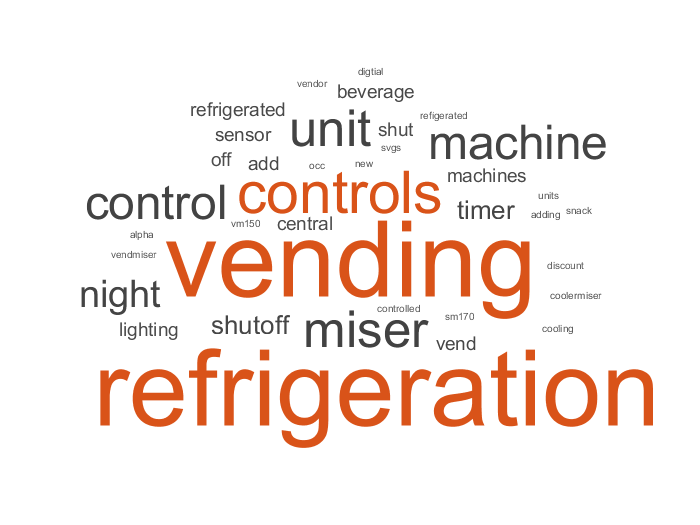

figure
NGram_CLoud1 = wordcloud(N_bag1);


N_bag2 = bagOfWords(Cluster_2_CL)

N_bag2 =   bagOfWords with properties:

          Counts: [23×43 double]
      Vocabulary: [1×43 string]
        NumWords: 43
    NumDocuments: 23


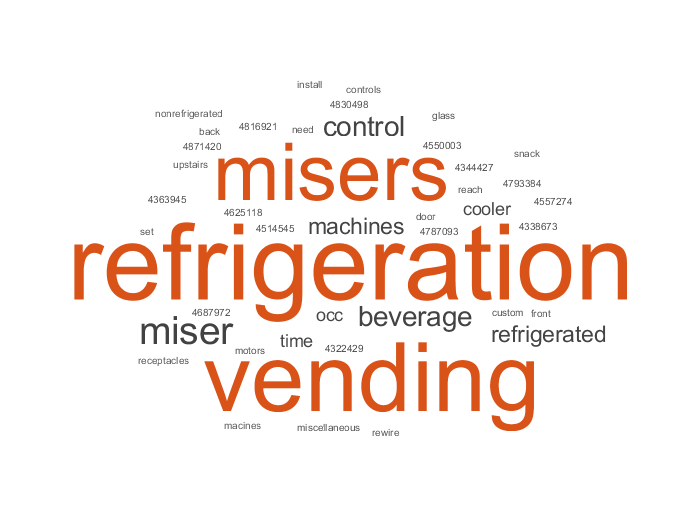

figure
NGram_CLoud2 = wordcloud(N_bag2);

function predata = preprocessText(textData)

predata=lower(textData);
predata=strtrim(predata);
predata=tokenizedDocument(predata);
predata=erasePunctuation(predata);
predata=removeStopWords(predata);
predata=removeShortWords(predata,2);

end